clear all
load Drone.mat

Y = y;

%lets form matrix A, u and v are 3x1 vectors, so A will be 6x6 matrix
%first three x values are u and rest values of x are v. x = [u;v]
A = eye(6);
A(1,4) = 1;
A(2,5) = 1;
A(3,6) = 1;
A

A =      1     0     0     1     0     0
     0     1     0     0     1     0
     0     0     1     0     0     1
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



% Q will also be 6x6 matrix, it is block diagonal
Q = eye(6);
Q(4,4) = 0.3^2;
Q(5,5) = 0.3^2;
Q(6,6) = 0.3^2;
Q

Q =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    0.0900         0         0
         0         0         0         0    0.0900         0
         0         0         0         0         0    0.0900



m0 = [0;0;0;0;0;0];
P0 = eye(6);
P0(1,1) = 10^2;
P0(2,2) = 10^2;
P0(3,3) = 10^2;
P0

P0 =    100     0     0     0     0     0
     0   100     0     0     0     0
     0     0   100     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


nk=100;        % number of steps

R = 4*eye(4);
noise=makedist('Normal','sigma',4)

noise =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 4



%bootstrap particle filter, copied from lecture 8 slides
N=3000; M=zeros(3,nk);
x=mvnrnd(repmat(m0,1,N)',P0)';
w=repmat(1/N,1,N);
w_random = mvnrnd(repmat(0,1,N)',10^2); % w0
for k=1:nk
 x=mvnrnd((A*x)',Q)'; 
 if ~isnan(Y(:,k))
 YY=repmat(Y(:,k),1,N);
 
 w_random = mvnrnd(w_random,0.01^2); %w_k
 w_bias = [w_random';w_random';w_random';w_random'];
 
 w=mvnpdf(Y(:,k)',(task2_h(x) + w_bias)',R)'; 
 
 w=w/sum(w);
 x=x(:,resamp(w));
 w=repmat(1/N,1,N); 
 end
 M(:,k)=mean(x(1:3,:),2);
end

rmse=sqrt(mean(sum((u_true(:,2:end)-M).^2,1)));

disp(['RMS error for bootstrap PF is ',num2str(rmse)])

RMS error for bootstrap PF is 10.0594


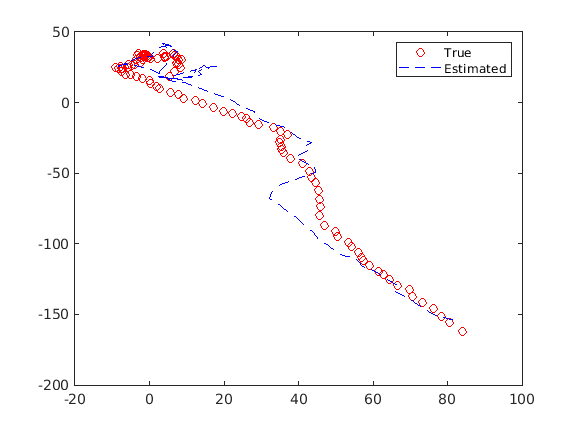


%plot 3D drone trajectories on 2D plane. I didn't plot 3D line because it
%would be almost impossible to see if filtered result was good or not(at least for me).
plot(u_true(1,:),u_true(2,:),'ro',M(1,:),M(2,:),'b--')
legend('True','Estimated')

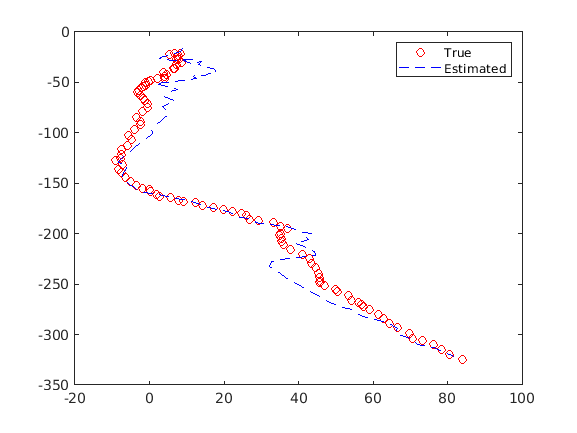


plot(u_true(1,:),u_true(3,:),'ro',M(1,:),M(3,:),'b--')
legend('True','Estimated')

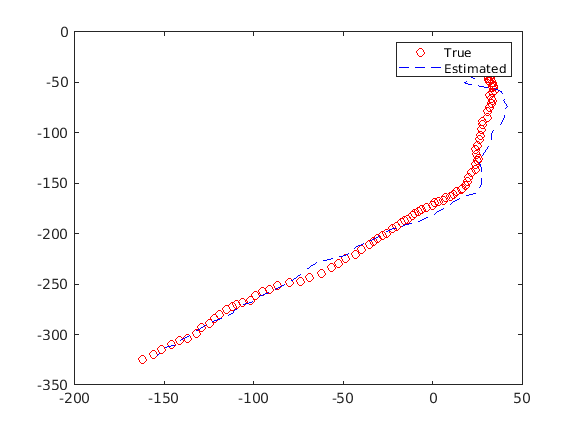


plot(u_true(2,:),u_true(3,:),'ro',M(2,:),M(3,:),'b--')
legend('True','Estimated')


%

% Rao-Blackwellised particle filter (version with H=0), H = 0 indicates
% that measurements doesn't depend on positions. So this algorithm samples
% only positions. Code taken from sub_demo.m
U = Q(1:3,1:3); %CHANGED
Qv = Q(4:6,4:6);%CHANGED
R = 4*eye(4); %CHANGED
F=eye(3); frb=@(u) u; Arb=eye(3); 
Nrb=3000; %CHANGED
Mrb=nan(3,nk);  % preallocation
u=mvnrnd(repmat(m0(1:3),1,Nrb)',P0(1:3,1:3))'; 
mrb=repmat(m0(4:6),1,Nrb);
Prb=P0(4:6,4:6);    % covariance evolves the same for all particles
w=ones(Nrb,1);

w_random = mvnrnd(repmat(0,1,Nrb)',10^2);
for k=1:nk
    d=mvnrnd((F*mrb)',F*Prb*F'+U)';
    u=frb(u)+d;
    [mrb,Prb]=kf_update(mrb,Prb,d,F,U);    % vectorized in mrb and d
    [mrb,Prb]=kf_predict(mrb,Prb,Arb,Qv);
    
    w_random = mvnrnd(w_random,0.01^2);
    w_bias = [w_random';w_random';w_random';w_random'];
    w=mvnpdf(Y(:,k)',(task2_h(u) + w_bias)',R)';
    w=w/sum(w);
    J=resamp(w); u=u(:,J); mrb=mrb(:,J);
    Mrb(:,k)=mean(u,2);
end

%rmse
rmse=sqrt(mean(sum((u_true(:,2:end)-Mrb).^2,1)));

disp(['RMS error for Rao-Blackwellised particle filter is ',num2str(rmse)])

RMS error for Rao-Blackwellised particle filter is 5.7973


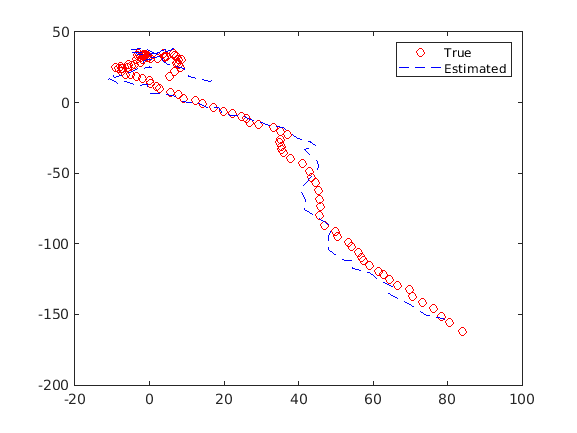


%plot
plot(u_true(1,:),u_true(2,:),'ro',Mrb(1,:),Mrb(2,:),'b--')
legend('True','Estimated')

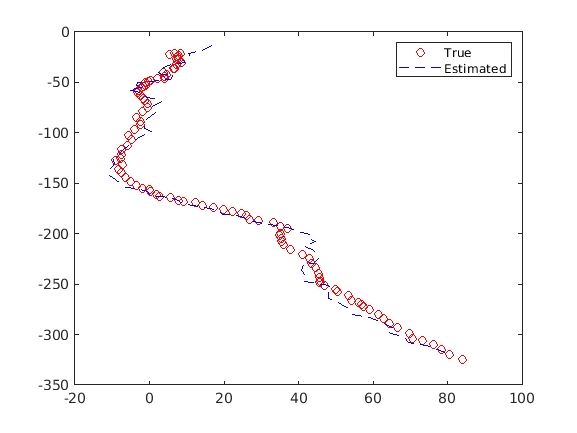


plot(u_true(1,:),u_true(3,:),'ro',Mrb(1,:),Mrb(3,:),'b--')
legend('True','Estimated')

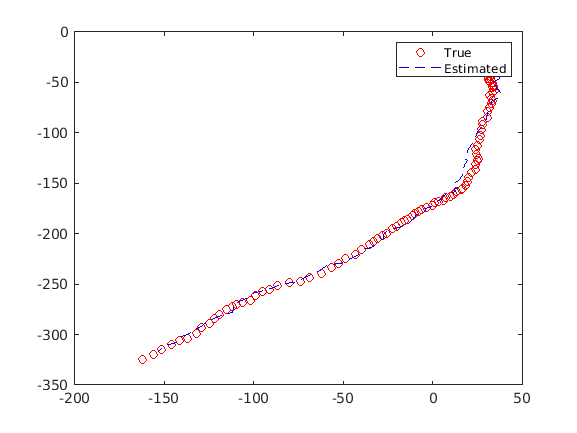


plot(u_true(2,:),u_true(3,:),'ro',Mrb(2,:),Mrb(3,:),'b--')
legend('True','Estimated')

Functions

function hval=task2_h(x)
s1 = [-20;10;0];
s2 = [30;0;-100];
s3 = [70;-100;-200];
s4 = [40;-150;-300];

hval(1,:) = sqrt((x(1,:)-s1(1)).^2 + (x(2,:)-s1(2)).^2 + (x(3,:)-s1(3)).^2);
hval(2,:) = sqrt((x(1,:)-s2(1)).^2 + (x(2,:)-s2(2)).^2 + (x(3,:)-s2(3)).^2);
hval(3,:) = sqrt((x(1,:)-s3(1)).^2 + (x(2,:)-s3(2)).^2 + (x(3,:)-s3(3)).^2);
hval(4,:) = sqrt((x(1,:)-s4(1)).^2 + (x(2,:)-s4(2)).^2 + (x(3,:)-s4(3)).^2);
end

%taken from lecture 8 slides
function J=resamp(W)
u=rand(length(W),1);
[~,J]=histc(u,[0;cumsum(W(:))]);
end

%taken from some slide
function [m,P] = kf_update(m,P,y,H,R)
v = y-H*m;
S = H*P*H'+R;
K = P*H'/S;     % /S is mathematically same as *inv(S) but faster & more accurate
m = m+K*v;
P = P-K*S*K';
end

function [m,P] = kf_predict(m,P,A,Q)
m = A*m;
P = A*P*A'+Q;
end